## Homework 2

### ADSI Problem 1.4: Filter decomposition

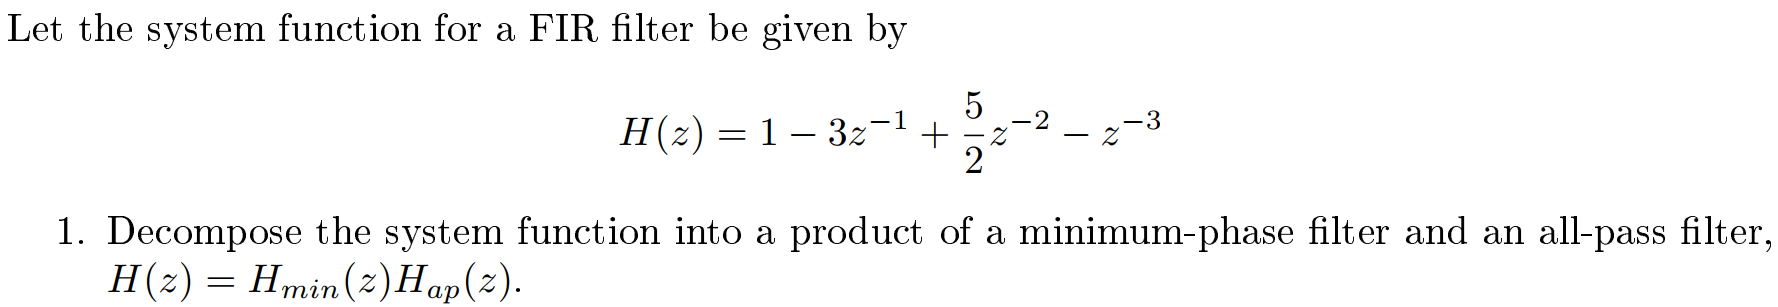

Any system funcrtion can be decomposed into a product of a minimum-phase filter and an all-pass filter using the following formula:

    
$$H\left(z\right)=H_{\mathrm{min}} \left(z\right)H_{\mathrm{ap}} \left(z\right)$$
  

The minimum phase filter can be computed as follows:

    
$$H_{\mathrm{min}} \left(z\right)=-\frac{1}{a^* }H_1 \left(z\right)\left(1-az^{-1} \right)$$


where $H_1 \left(z\right)$ corresponds to the part of the transfer function where zeros are inside the unit circle and $a=\frac{1}{{z_0 }^* }$ and $z_0$ is the zero outside the unit circle.

The allpass filter can be calculated:

    
$$H_{\mathrm{ap}} \left(z\right)=\frac{z^{-1} -a^* }{1-az^{-1} }$$


The filter decomposition algorithm has following steps:

- convert transfer function into pole-zero representation in order to find the zeros that are outside the unit circle

- compute $a$ and its conjugate $a^*$

- find $H_1 \left(z\right)$ which corresponds to the part of the transfer function where zeros are inside the unit circle

- plugin the numbers for the formula for the minimum-phase filter

- plugin the numbers for the formula for the allpass filter 

- put everything together:

**Step 1:** convert transfer function into pole-zero representation in order to find the zeros that are outside the unit circle

zeros = roots([1, -3, 5/2, -1])

zeros =    2.0000 + 0.0000i
   0.5000 + 0.5000i
   0.5000 - 0.5000i


The zero-pole representation of the transfer function is:


$$\begin{array}{l}
H\left(z\right)=\left(1\right)\left(1-2z^{-1} \right)\left(1-\left(0\ldotp 5+0\ldotp 5\jmath \right)z^{-1} \right)\left(1-\left(0\ldotp 5-0\ldotp 5\jmath \right)z^{-1} \right)\\
H\left(z\right)=1\left(1-2z^{-1} \right)\left(0\ldotp 5-0\ldotp 5\jmath \;z^{-1} \right)\left(0\ldotp 5+0\ldotp 5\jmath z^{-1} \;\right)
\end{array}$$


To find the zero $z_0$ that is outside the unit circle, we can plot zplane:

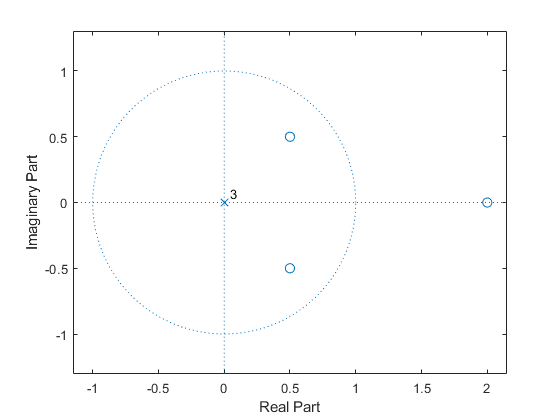

zplane([1, -3, 5/2, -1]);

In this exercise, the zero outside the unit circle is $z_0 =2$.

**Step 2:** compute $a$ and its conjugate $a^*$


$$a=\frac{1}{z_0 }=\frac{1}{2}$$



$$a^* ={\left(\frac{1}{z_0 }\right)}^* ={\left(\frac{1}{2}\right)}^* =\frac{1}{2}$$


**Step 3:** find $H_1 \left(z\right)$ which corresponds to the part of the transfer function where zeros are inside the unit circle

The zero-pole representation of the transfer function is:


$$H\left(z\right)=\left(1\right)\left(1-2z^{-1} \right)\left(1-\left(0\ldotp 5+0\ldotp 5\j \right)z^{-1} \right)\left(1-\left(0\ldotp 5-0\ldotp 5\j \right)z^{-1} \right)$$


therefore $H_1 \left(z\right)$is


$$H_1 \left(z\right)=\left(1-\left(0\ldotp 5+0\ldotp 5\j \right)z^{-1} \right)\left(1-\left(0\ldotp 5-0\ldotp 5\j \right)z^{-1} \right)$$


**Step 4**: plugin the numbers for the formula for minimum-phase filter


$$H_{\min } \left(z\right)=-\frac{1}{a^* }H_1 \left(z\right)\left(1-az^{-1} \right)$$



$$\begin{array}{l}
H_{\mathrm{min}} \left(z\right)=-\frac{1}{\left(\frac{1}{2}\right)}\left(1-\left(0\ldotp 5+0\ldotp 5\j \right)z^{-1} \right)\left(1-\left(0\ldotp 5-0\ldotp 5\j \right)z^{-1} \right)\left(1-0\ldotp 5z^{-1} \right)\\
H_{\mathrm{min}} \left(z\right)=-2\left(1-\left(0\ldotp 5+0\ldotp 5\j \right)z^{-1} \right)\left(1-\left(0\ldotp 5-0\ldotp 5\j \right)z^{-1} \right)\left(1-0\ldotp 5z^{-1} \right)
\end{array}$$


The minimim-phase filter should have all its zeros inside the unit cirlce:

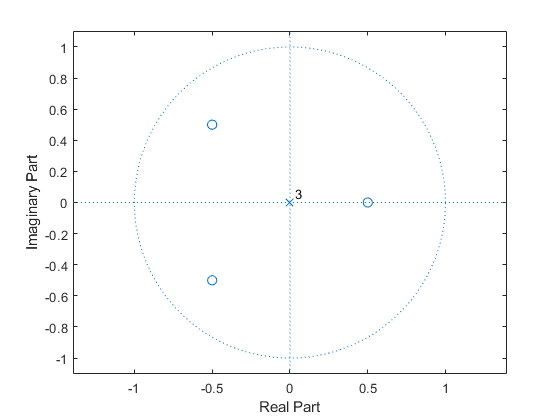

b0 = -2;
b1 = [1, 0.5+0.5i];
b2 = [1, 0.5-0.5i];
b3 = [1,-0.5];
b = b0 * conv(conv(b1, b2), b3);
zplane(b);

We can use Matlab function `isminphase(b,a)` to determine whether a filter is a minimum-phase filter.

isminphase(b)

ans = logical
   1


**Step 5:** compute the allpass filter :


$$H_{\mathrm{ap}} \left(z\right)=\frac{z^{-1} -a^* }{1-az^{-1} }$$



$$H_{\mathrm{ap}} \left(z\right)=\frac{z^{-1} -0\ldotp 5}{1-0\ldotp 5z^{-1} }$$


**Step 6:** put everything together:


$$\begin{array}{l}
H_{\mathrm{min}} \left(z\right)=-2\left(1-\left(0\ldotp 5+0\ldotp 5\j \right)z^{-1} \right)\left(1-\left(0\ldotp 5-0\ldotp 5\j \right)z^{-1} \right)\left(1-0\ldotp 5z^{-1} \right)\\
H_{\mathrm{ap}} \left(z\right)=\frac{z^{-1} -0\ldotp 5}{1-0\ldotp 5z^{-1} }
\end{array}$$



$$H\left(z\right)=H_{\mathrm{min}} \left(z\right)H_{\mathrm{ap}} \left(z\right)$$



$$H\left(z\right)=-2\left(1-\left(0\ldotp 5+0\ldotp 5\j \right)z^{-1} \right)\left(1-\left(0\ldotp 5-0\ldotp 5\j \right)z^{-1} \right)\left(1-0\ldotp 5z^{-1} \right)\left(\frac{z^{-1} -0\ldotp 5}{1-0\ldotp 5z^{-1} }\right)$$
